# EEE3548 Exercise #2 Basic Image Processing

## [2019142047] [Jeon Minsu]

#### In this exercise, we will review the basic concepts in linear imaging systems.

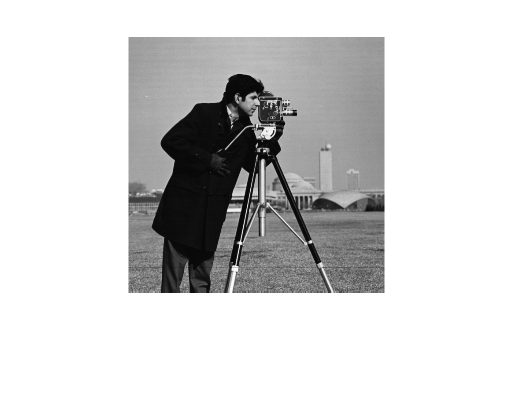

test_img = imread('cameraman.tif'); % read cameraman as test image
imshow(test_img);                   % show test image

#### Q1. Create a Line impuse image $\delta(x)$

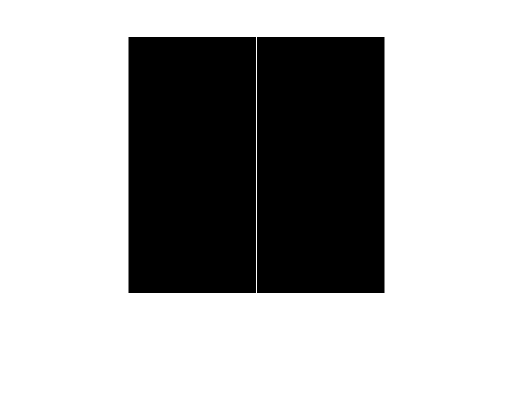

[M,N] = size(test_img); % size of image
x = -M/2:(M-1)/2;       % x-axis
y = -N/2:(N-1)/2;       % y-axis
[X,Y] = meshgrid(x,y);
imp_lin = zeros(N,M);
imp_lin(X == 0) = 1;    % make line impulse function
imshow(imp_lin);        % show line impulse function

#### Q2. Create line impulse at angle $-\pi/3$ at distance of 10 pixels from the center. 

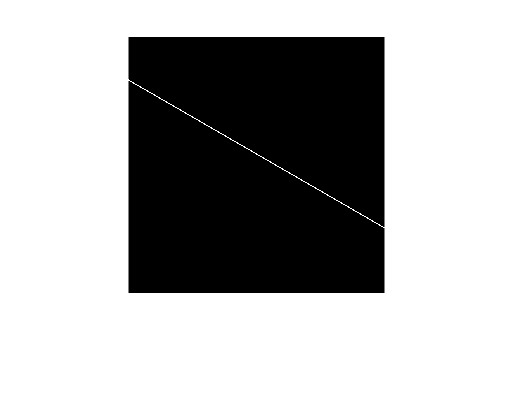

[M,N] = size(test_img); % size of image
x = -M/2:(M-1)/2;       % x-axis
y = -N/2:(N-1)/2;       % y-axis
a = -pi/3;              % rotate angle
[X,Y] = meshgrid(x,y);
imp_lin_rot = zeros(N,M);
imp_lin_rot( round(X * cos(a) + Y * sin(a)) == 10 ) = 1;    % make rotated line impulse function
imshow(imp_lin_rot);                                        % show rotated line impulse function

#### Q3. Get the pixel values of the test image along the line in Q2 and plot it

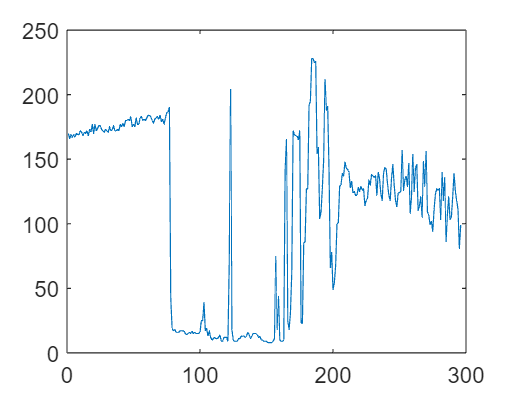

[A, B] = find(imp_lin_rot == 1);        % get coordinates of imp_lin_rot = 1
pixel_img = improfile( test_img, A, B); % get pixel values of this coordinates
plot(pixel_img);                        % show pixel values

## Point spread function

The output image of a linear shift-invariant image system is the result of the convolution between the input and the impulse response, or the point spread function.


$$g(x,y)=f(x,y)\ast h(x,y)$$


Now, let's define a sample 2D PSF. For example, let's imagine a linear shift-invariant imaging system whose PSF is a 2D gaussian. 2D Gaussian is defined as


$$h(x,y)=\frac{1}{2\pi \sigma^2}e^{-(x^2+y^2)/2\sigma^2}$$


#### Q4. Implement a 2D gaussian PSF with sigma of 2 pixels. 

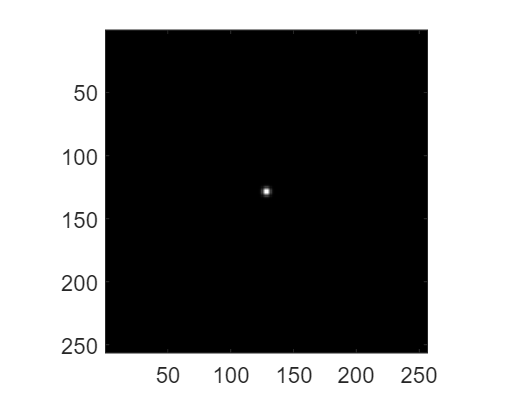

[M,N] = size(test_img);      % size of image
x = linspace(-M/2,M/2,M);    % x-axis
y = linspace(-N/2,N/2,N);    % y-axis
[X, Y] = meshgrid(x, y);
sigma = 2;                   % sigma is 2

psf = (1/2*pi*sigma^2)*(exp(-(X.^2+Y.^2) / (2*sigma^2))); % make 2D gaussian function
imagesc(psf);axis image;colormap gray;                    % show 2D gaussian function

#### Q5. In the previous exercise, we implemented 1d convolution using FFT. Here, we will implement fast 2D convolution using 2d FFTs. Use fft2, ifft2, fftshifts/ifftshifts wisely to implement fast 2D convolution (See [https://kr.mathworks.com/help/matlab/ref/fft2.html](https://kr.mathworks.com/help/matlab/ref/fft2.html) for details). Check your results by convolving the cameraman with the gaussian PSF.

Hint : You can use [padarray](https://kr.mathworks.com/help/images/ref/padarray.html) to match the sizes of the psf and the image.

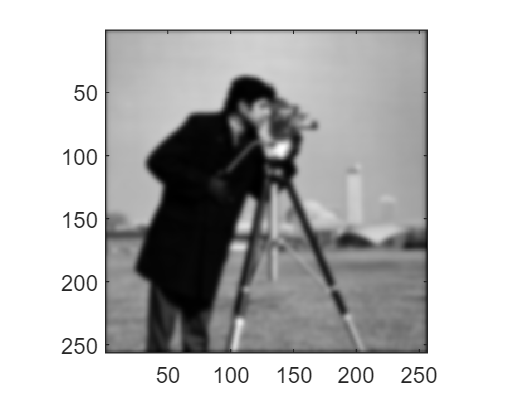

filtered_img = fftconv2d(test_img, psf);          % use fftconv2d function

imagesc(filtered_img);axis image;colormap gray;   % show filtered image using fftconv2d function

#### Q6. MATLAB has built-in 2D convolution.([https://kr.mathworks.com/help/matlab/ref/conv2.html](https://kr.mathworks.com/help/matlab/ref/conv2.html)) Compare your results with the built-in 2d conv. How well is your fftconv doing?

C = conv2(test_img, psf, 'same');        % use built-in 2D convolution

imagesc(C);axis image;colormap gray;     % show filtered image using built-in 2D convolution

**A : Fftconv that I made is very similar to 'built-in 2D convolution'.**

#### Q7. Take the Fourier transform of the cameraman image and plot its spectrum. The spectrum needs to be plotted in log in order to view all frequency components.

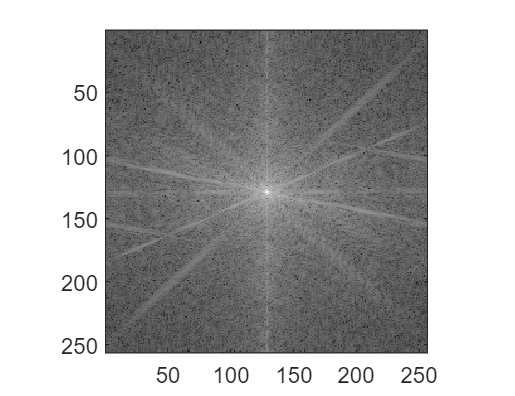

fimage = fftshift(fft2(test_img));                  % take the fourier transform for test image
imagesc(log(abs(fimage)));axis image;colormap gray; % show transfored test image in log scale

#### Q8. Now try the FT of the test image convolved with the 2D gaussian PSF. How does it differ from the previous result? What does it mean

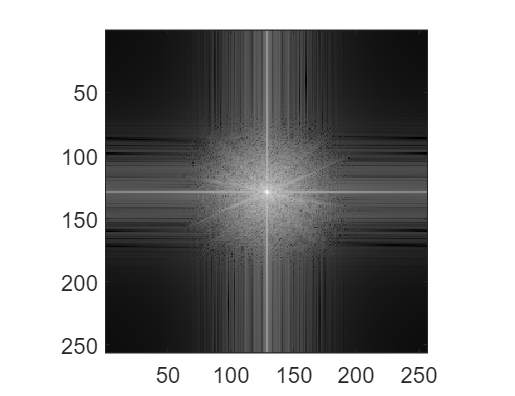

ffiltered_img = fftshift(fft2(filtered_img));                % take the fourier transform for filtered image
imagesc(log(abs(ffiltered_img)));axis image;colormap gray;   % show transfored filtered image in log scale

**A : Compared to the previous result, the high frequency parts are being erased (filtered). It means that the delicate part of the test image has disappeared and is being blurred.**

#### Q9. Plot the magnitude spectrum of this imaging system and describe how this system transforms your image in the spatial frequency domain. 

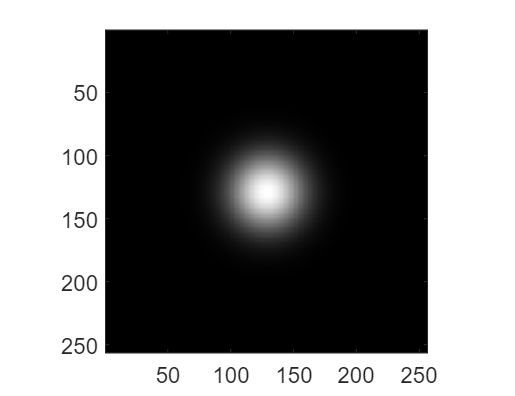

fpsf = fftshift(fft2(psf));
imagesc(abs(fpsf));axis image;colormap gray;

**A : The magnitude of high frequency parts are almost 0 and there's only low frequency part. So, this system transforms image blurred.**

**Specifically, ** **the image quality of a part requiring fine expression is degraded.**

## Optical Transfer Function

Point spread function is a Fourier transform of the transfer function of the imaging system. An imaging system, for example a camera, behaves like an ideal low-pass filter with a fixed cut-off frequency. An ideal low pass filter in the Fourier domain can be written as;


$$H(k_x, k_y) = \begin{cases}1 \text{, for } k_x^2 + k_y^2 \leq k_c^2 \\ 0 \text{, for } k_x^2 + k_y^2 > k_c^2 \end{cases}$$


In this problem, we will design a transfer function of an ideal camera, whose cut-off frequency is $k_c$ = 8 cycles per mm. To compute the spatial frequency values, let's assume that a pixel is 0.01mm.

#### Q10. Create an image of sinusoidal stripes with fixed spatial frequencies of  3, 10, 20 cycles per mm in different directions (your choice). To evaluate spatial frequency in units of cycles per mm, we will assign a physical size (0.01 mm) to a pixel.

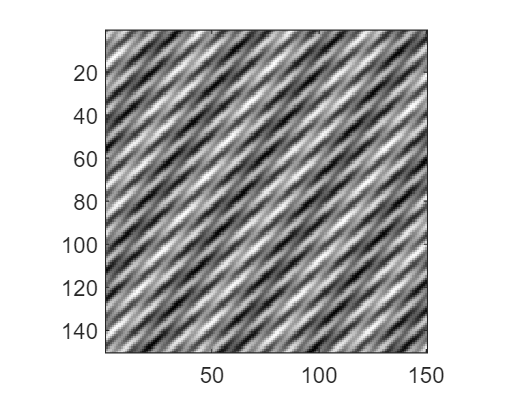

N = 150;
psize = 0.01;                   % physical size (0.01 mm)

x = linspace(0, N, N) * psize;  % x-axis
y = linspace(0, N, N) * psize;  % y-axis
[X,Y] = meshgrid(x,y);

theta1 = pi/6;                  % direction 1
kx1 = 3 * cos(theta1);          % x part of 3 cycles sinusoidal stripe
ky1 = 3 * sin(theta1);          % y part of 3 cycles sinusoidal stripe

theta2 = pi/3;                  % direction 2
kx2 = 10 * cos(theta2);         % x part of 10 cycles sinusoidal stripe
ky2 = 10 * sin(theta2);         % y part of 10 cycles sinusoidal stripe

theta3 = pi/4;                  % direction 3
kx3 = 20 * cos(theta3);         % x part of 20 cycles sinusoidal stripe
ky3 = 20 * sin(theta3);         % y part of 20 cycles sinusoidal stripe

stripes = 3*ones(N,N) + 2*sin(2*pi*(kx1*X+ky1*Y)) + 3*sin(2*pi*(kx2*X+ky2*Y)) + 3*sin(2*pi*(kx3*X+ky3*Y)); % create an image of sinusoidal stripes
imagesc(stripes);axis image;colormap gray; % show an image of sinusoidal stripes

#### Q11. Design the ideal OTF and see what the output image should be when the input is the image computed in �Q10. How does the result look?

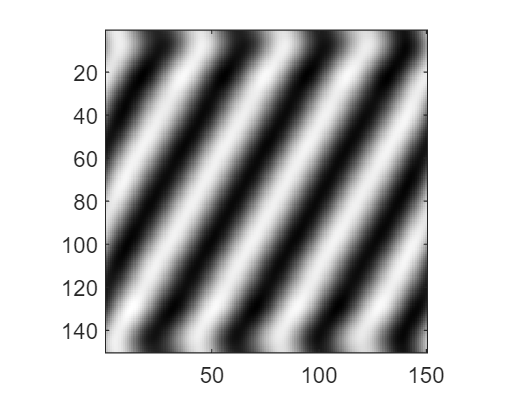

[M,N] = size(stripes);
x = linspace(-M/2,M/2,M);        % x-axis
y = linspace(-N/2,N/2,N);        % y-axis

[k_x, k_y] = meshgrid(x, y);
k_c = 8;                         % cut-off frequency is 8

otf = zeros(M,N);
otf( k_x.^2 + k_y.^2 <= k_c^2 ) = 1;        % create ideal OTF
fstripes = (fftshift(fft2(stripes)));       % fourier transform for stripes
C = ifft2(ifftshift(fstripes.*otf));        % use OFT to filter an image
imagesc(abs(C));axis image;colormap gray;   % show filtered image 

**A : It almost looks like there is one sinusoidal wave, 3 cycles sinusoidal stripe (direction 1).**

**That's because high frequency (higer than cut-off frequency) is being blurred.**

#### Q12. Now, use the same OTF to compute the output image when the input object is the cameraman image.

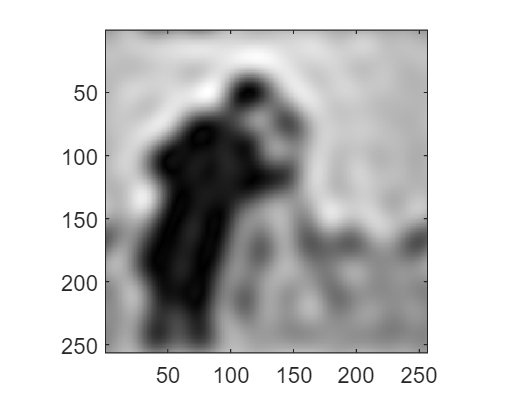

[M,N] = size(test_img);
x = linspace(-M/2,M/2,M);       % x-axis
y = linspace(-N/2,N/2,N);       % y-axis

[k_x, k_y] = meshgrid(x, y);    
k_c = 8;                       % same cut-off frequency

otf = zeros(M,N);
otf( k_x.^2 + k_y.^2 <= k_c^2 ) = 1;      % same ideal OTF
ftest_img = (fftshift(fft2(test_img)));   % fourier transform for test image
C = ifft2(ifftshift(ftest_img.*otf));     % use OFT to filter an test image
imagesc(abs(C));axis image;colormap gray; % show filtered test image 

#### Q13. What is the PSF of this imaging system? Plot the PSF and Compute the resolution of this imaging system in units of mm.

% Your code here

# Functions

function x = fftconv2d(image, psf)       % make 2D convolution function

    image_zero = padarray(image, [length(psf) length(psf)], 'post');    % zero-padding for image
    psf_zero = padarray(psf, [length(image) length(image)], 'post');    % zero-padding for psf

    fimage = fftshift(fft2(image_zero));                                % fourier transform for zero-padded image
    fpsf = fftshift(fft2(psf_zero));                                    % fourier transform for zero-padded psf
    out = (ifft2(ifftshift(fimage.*fpsf)));                             % multiple of frequency domain (it's covolution of time domain)

    win1 = centerCropWindow2d(size(out), [length(image) length(image)]);    % create a center crop window for disered section
    x = imcrop(out, win1);                                                  % crop the output image using the center crop window
 
end
